% clc
% vidReader = VideoReader('visiontraffic.avi','CurrentTime',11);
% opticFlow = opticalFlowLK('NoiseThreshold',0.009);
% 
% h = figure;
% movegui(h);
% hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
% hPlot = axes(hViewPanel);
% cmap = colormap("jet")
% 
% while hasFrame(vidReader)
%     frameRGB = readFrame(vidReader);
%     frameGray = im2gray(frameRGB);
%     flow = estimateFlow(opticFlow,frameGray);
%     imshow(frameRGB)
%     hold on
% %     plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
%     imshow(flow.Magnitude, 'Parent',hPlot, Colormap=cmap)
%     hold off
%     pause(10^-3)
% end

dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
dcmImgs = medfilt3(dcmHandler.readAllImage());

% [u,v] = scripts.opticalFlowHandler.lkofloop(dcmImgs, 'd');
% uv = sqrt(u.*u + v.*v);
% size(uv)
cmap = colormap("jet");
% 
% for i = 1:size(uv, 3)
%     imshow(uv(:,:,i), Colormap=cmap)
%     
%     pause(10^-3)
% end

% 
% 
% 
opticalFlowInstance = opticalFlowLK("NoiseThreshold", 10)

opticalFlowInstance =   opticalFlowLK のプロパティ:

    NoiseThreshold: 10


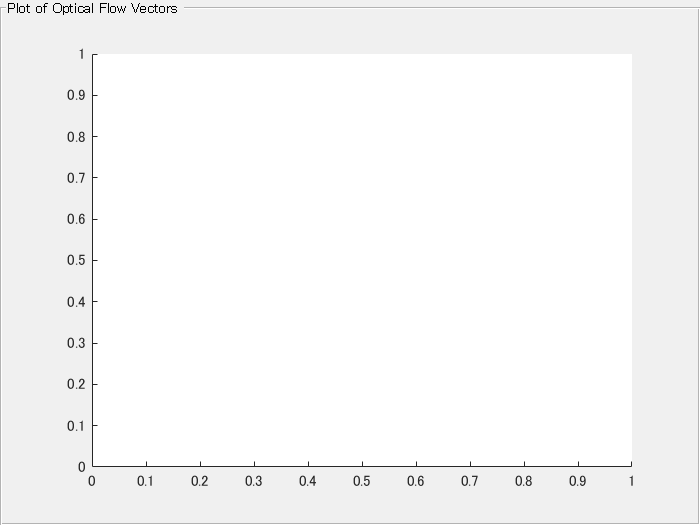


h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);
cmap = colormap("jet");

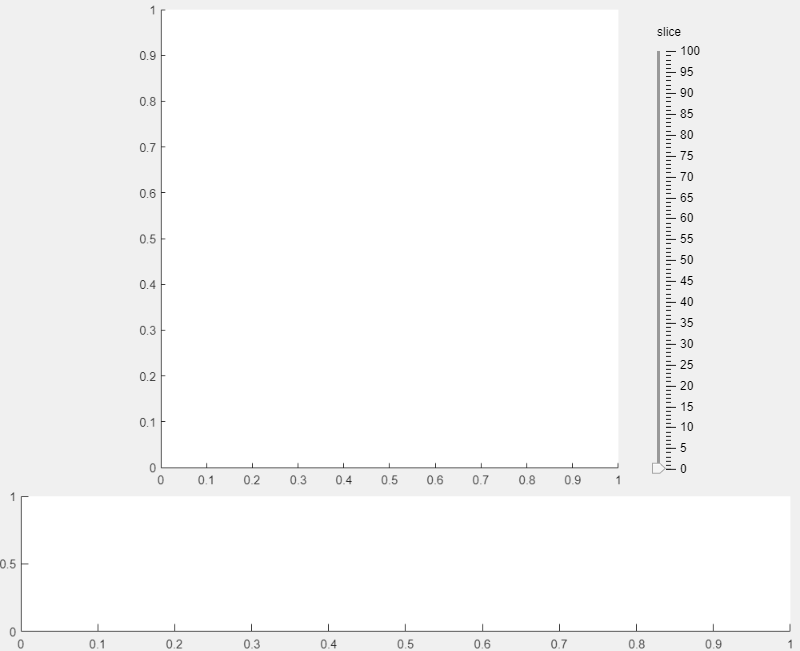

使い方によるエラー categorical
既定のカテゴリ名を作成できません。CATEGORYNAMES
入力引数を使用してカテゴリ名を指定してください。

エラー: scripts.measureTools.nobinHistogrammer/setData (行 88)
            this.sourceCategoryArray = categorical(reshape(array2D, [1, numel(array2D)]));

エラー: 

flow = cell(size(dcmImgs, 3));
flow3D = zeros(size(dcmImgs));
for i = 1:size(dcmImgs, 3)
    flow{i} = estimateFlow(opticalFlowInstance, dcmImgs(:,:,i));
    flow3D(:,:,i) = flow{i}.Magnitude;
end
scripts.imageViewer.guiImageViewer('image3D', flow3D)